import casadi.*

disp('=== 2. FÁZIS: Klasszikus vs. AI MPC Szimuláció és Összehasonlítás ===');

=== 2. FÁZIS: Klasszikus vs. AI MPC Szimuláció és Összehasonlítás ===



% Ellenőrzés
if ~exist('net', 'var')
    error('Hiba: Nem találom a "net" (NN) változót a Workspace-ben!');
end

% --- TÖBB KÖR EGYMÁS UTÁN FŰZÉSE ---
korok_szama = 1; 
egy_kor_pontjai = smooth_path(1:end-1, :); 
multi_lap_path = repmat(egy_kor_pontjai, korok_szama, 1);
multi_lap_path = [multi_lap_path; smooth_path(end, :)];

Ts = 0.1; 
V_target = 5; 
N = 15; 

ds = sqrt(diff(multi_lap_path(:,1)).^2 + diff(multi_lap_path(:,2)).^2);
dist = [0; cumsum(ds)];
t_path = dist / V_target; 
t_sim = 0:Ts:t_path(end); 

X_ref = interp1(t_path, multi_lap_path(:,1), t_sim, 'linear', 'extrap');
Y_ref = interp1(t_path, multi_lap_path(:,2), t_sim, 'linear', 'extrap');
Vx_ref = [diff(X_ref)/Ts, 0]; 
Vy_ref = [diff(Y_ref)/Ts, 0];
RefMatrix = [X_ref', Y_ref', Vx_ref', Vy_ref'];

% 2. Dinamika 
A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1];
B = [0 0; 0 0; Ts 0; 0 Ts];

% 3. LQR
Q_lqr = diag([10, 10, 1, 1]);
R_lqr = diag([0.5, 0.5]);
K_lqr = dlqr(A, B, Q_lqr, R_lqr);

% ==========================================
% 4. CASADI OPTIMIZÁCIÓS PROBLÉMA FELÉPÍTÉSE
% ==========================================
opti = casadi.Opti();

X = opti.variable(4, N+1); 
U = opti.variable(2, N);   

x0_param = opti.parameter(4, 1);         
ref_param = opti.parameter(4, N+1);      
w_nn_param = opti.parameter(4, 1); 

Q_mpc = diag([100, 100, 0, 0]); 
R_mpc = diag([0.1, 0.1]);     

cost = 0;
for k = 1:N
    err = X(:, k) - ref_param(:, k);
    cost = cost + err' * Q_mpc * err + U(:, k)' * R_mpc * U(:, k);
    opti.subject_to(X(:, k+1) == A * X(:, k) + B * U(:, k) + w_nn_param);
end
err_N = X(:, N+1) - ref_param(:, N+1);
cost = cost + err_N' * Q_mpc * err_N;

opti.minimize(cost);
opti.subject_to(X(:, 1) == x0_param);

u_tight_base = 20; 
opti.subject_to( -(u_tight_base) <= U <= (u_tight_base) );

p_opts = struct('expand', true); 
s_opts = struct('max_iter', 100, 'print_level', 0, 'acceptable_tol', 1e-6); 
opti.solver('ipopt', p_opts, s_opts);

% ==========================================
% 5. SZIMULÁCIÓS HUROK (Két futás egymás után)
% ==========================================
n_steps = length(t_sim) - N - 1;

% Adattárolók a két futáshoz
history_cl = zeros(n_steps, 4); errors_cl = zeros(n_steps, 1);
history_ai = zeros(n_steps, 4); errors_ai = zeros(n_steps, 1);

for mode = 1:2
    if mode == 1
        disp('--> 1/2. Szimuláció fut: KLASSZIKUS MPC (AI nélkül)...');
        use_nn = false;
    else
        disp('--> 2/2. Szimuláció fut: AI-VAL SEGÍTETT MPC...');
        use_nn = true;
    end
    
    % Alapállapotok visszaállítása a futás elején
    x_real = RefMatrix(1,:)'; 
    z_nom = x_real;           
    u_prev = [0; 0];
    x_real_prev = x_real;
    
    for k = 1 : n_steps
        current_ref = RefMatrix(k : k+N, :)';
        
        % --- AI Jóslat ---
        if use_nn
            nn_input = dlarray([x_real_prev; u_prev], 'CB'); 
            w_becsult = double(extractdata(predict(net, nn_input)));
            w_becsult = w_becsult(:); 
        else
            w_becsult = [0; 0; 0; 0]; 
        end
        
        % --- CasADi ---
        opti.set_value(x0_param, z_nom);       
        opti.set_value(ref_param, current_ref);
        opti.set_value(w_nn_param, w_becsult); 
        
        try
            sol = opti.solve(); 
            v_k_opt = sol.value(U(:, 1)); 
        catch
            v_k_opt = opti.debug.value(U(:, 1)); 
        end
        
        % --- LQR ---
        u_k = v_k_opt - K_lqr * (x_real - z_nom);
        u_k = max(min(u_k, 25), -25);
        
        % --- TISZTA FIZIKA ---
        drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts;
        drag_y = -0.02 * x_real(4) * abs(x_real(4)) * Ts;
        const_wind_x = 0.8 * Ts; 
        const_wind_y = 0.5 * Ts;

        % Teljesen determinisztikus teszt (zaj = 0)
        w_x = const_wind_x + drag_x;
        w_y = const_wind_y + drag_y;
        w_k = [0; 0; w_x; w_y];
        
        % Léptetések
        x_real = A * x_real + B * u_k + w_k;
        z_nom = A * z_nom + B * v_k_opt + w_becsult; 
        
        % Mentés a következő lépéshez
        u_prev = u_k;
        x_real_prev = x_real;
        
        % Adatok rögzítése
        % VALÓDI Keresztirányú hiba (Cross-Track Error) számítása:
        % Megkeressük a zöld útvonal összes pontja közül a legközelebbit az autóhoz
        tavolsagok = sqrt((smooth_path(:,1) - x_real(1)).^2 + (smooth_path(:,2) - x_real(2)).^2);
        valodi_terbeli_hiba = min(tavolsagok);

        if mode == 1
            history_cl(k, :) = x_real';
            errors_cl(k) = valodi_terbeli_hiba; % Időbeli hiba helyett térbeli
        else
            history_ai(k, :) = x_real';
            errors_ai(k) = valodi_terbeli_hiba; % Időbeli hiba helyett térbeli
        end
    end
end

--> 1/2. Szimuláció fut: KLASSZIKUS MPC (AI nélkül)...


      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  23.00us (  3.29us)         7
       nlp_g  |        0 (       0)  52.00us (  7.43us)         7
  nlp_grad_f  |        0 (       0)  26.00us (  3.25us)         8
  nlp_hess_l  |        0 (       0)  15.00us (  2.50us)         6
   nlp_jac_g  |        0 (       0)  32.00us (  4.00us)         8
       total  |  32.00ms ( 32.00ms)  32.60ms ( 32.60ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  22.00us (  3.14us)         7
       nlp_g  |        0 (       0)  44.00us (  6.29us)         7
  nlp_grad_f  |        0 (       0)  26.00us (  3.25us)         8
  nlp_hess_l  |        0 (       0)  14.00us (  2.33us)         6
   nlp_jac_g  |        0 (       0)  31.00us (  3.87us)         8
       total  |  17.00ms ( 17.00ms)  17.44ms ( 17.44ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

--> 2/2. Szimuláció fut: AI-VAL SEGÍTETT MPC...


      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  10.00us (  1.43us)         7
       nlp_g  |        0 (       0)  18.00us (  2.57us)         7
  nlp_grad_f  |        0 (       0)  18.00us (  2.25us)         8
  nlp_hess_l  |        0 (       0)   6.00us (  1.00us)         6
   nlp_jac_g  |        0 (       0)  20.00us (  2.50us)         8
       total  |   9.00ms (  9.00ms)   9.32ms (  9.32ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  60.00us (  8.57us)         7
       nlp_g  |        0 (       0)  14.00us (  2.00us)         7
  nlp_grad_f  |        0 (       0)  22.00us (  2.75us)         8
  nlp_hess_l  |        0 (       0)   7.00us (  1.17us)         6
   nlp_jac_g  |        0 (       0)  13.00us (  1.62us)         8
       total  |        0 (       0)   8.74ms (  8.74ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp


% ==========================================
% 6. GRAFIKUS KIÉRTÉKELÉS (Teljes Sötét Mód)
% ==========================================
disp('=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===');

=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===


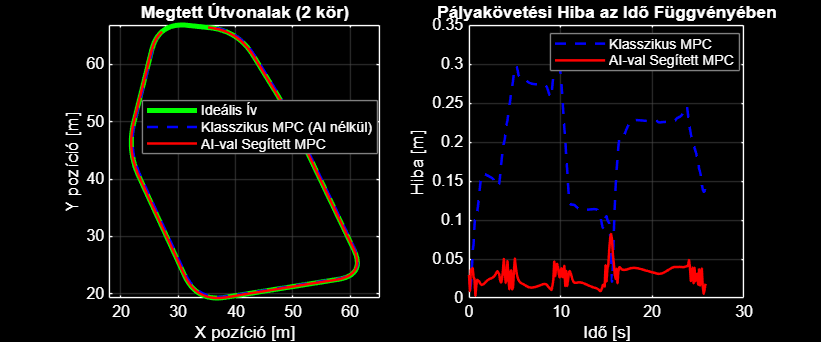


% A fő ablak háttere fekete ('Color', 'k')
figure('Name', 'MPC Összehasonlítás: Klasszikus vs. AI', 'Position', [100, 100, 1200, 500], 'Color', 'k');

% --- BAL OLDAL: Útvonalak ---
ax1 = subplot(1, 2, 1);
plot(smooth_path(:,1), smooth_path(:,2), '-g', 'LineWidth', 3, 'DisplayName', 'Ideális Ív'); hold on; grid on;
plot(history_cl(:,1), history_cl(:,2), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Klasszikus MPC (AI nélkül)');
plot(history_ai(:,1), history_ai(:,2), 'r-', 'LineWidth', 1.5, 'DisplayName', 'AI-val Segített MPC');
lgd1 = legend('Location', 'best');
title('Megtett Útvonalak (2 kör)', 'Color', 'w');
xlabel('X pozíció [m]', 'Color', 'w'); ylabel('Y pozíció [m]', 'Color', 'w');
axis equal;

% Tengelyszínek, rácsok és a legenda formázása sötét módhoz
set(ax1, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', [0.3 0.3 0.3], 'GridAlpha', 0.5);
set(lgd1, 'TextColor', 'w', 'Color', 'k', 'EdgeColor', [0.5 0.5 0.5]);


% --- JOBB OLDAL: Követési hiba ---
ax2 = subplot(1, 2, 2);
plot(t_sim(1:n_steps), errors_cl, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Klasszikus MPC'); hold on; grid on;
plot(t_sim(1:n_steps), errors_ai, 'r-', 'LineWidth', 1.5, 'DisplayName', 'AI-val Segített MPC');
lgd2 = legend('Location', 'best');
title('Pályakövetési Hiba az Idő Függvényében', 'Color', 'w');
xlabel('Idő [s]', 'Color', 'w'); ylabel('Hiba [m]', 'Color', 'w');

% Tengelyszínek, rácsok és a legenda formázása sötét módhoz
set(ax2, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', [0.3 0.3 0.3], 'GridAlpha', 0.5);
set(lgd2, 'TextColor', 'w', 'Color', 'k', 'EdgeColor', [0.5 0.5 0.5]);



% --- STATISZTIKA A KONZOLRA ---
mean_cl = mean(errors_cl);
mean_ai = mean(errors_ai);
javulas = (1 - (mean_ai / mean_cl)) * 100;

fprintf('\n=== EREDMÉNYEK ===\n');


=== EREDMÉNYEK ===


fprintf('Klasszikus MPC átlagos hiba:   %.4f m\n', mean_cl);

Klasszikus MPC átlagos hiba:   0.1949 m


fprintf('AI-val segített MPC hiba:      %.4f m\n', mean_ai);

AI-val segített MPC hiba:      0.0279 m


fprintf('--------------------------------------\n');

--------------------------------------


if javulas > 0
    fprintf('JAVULÁS AZ AI-VAL:            +%.1f %%\n', javulas);
else
    fprintf('ROMLÁS AZ AI-VAL:             %.1f %%\n', javulas);
    disp('Javaslat: Ellenőrizd a hálózat előjelét (w_becsult)!');
end

JAVULÁS AZ AI-VAL:            +85.7 %
